# Curvas de linealidad con diferentes tipos de entrada en el modelo

## Presa - Depredador

Tomaremos el modelo presa depredador:


$$\dot{P}(t)= \alpha P(t) - \beta P(t)D(t)\\
\dot{D}(t)= \delta P(t) D(t) - \gamma D(t)$$


**Con los siguientes parámetros y estados:**

$P(t)$: Número de presas en el tiempo

$D(t)$: Depredadores en el tiempo

$\alpha$: Tasa instantánea de aumento de presas en ausencia de depredadores

$\beta$: Tasa de cacería de número de presas por depredador

$\delta$: Tasa de aumento de depredadores por presa cazada

$\gamma$: Tasa instantánea de disminución de depredadores en ausencia de presas

Primero, definimos las condiciones iniciales y parámetros a utilizar en el modelo

addpath("Modelos")
%condiciones iniciales
P0 = 3;
D0 = 3;

%Parametros
alpha = 1;
beta = 1;
delta = 1;
gamma = 1;

%Tiempo de simulacion
Time = 100;

## **Ejemplos de curvas de linealidad con diferentes tipos de entrada **

**Entrada constante**

1. Definición de la entrada para observar el comportamiento general del modelo

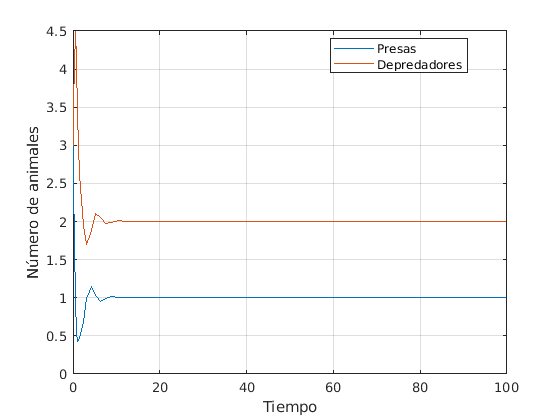

%entrada
u = 1;

options = simset('SrcWorkspace','current');
sim('PresaDepredador_ejm2',[],options);

figure
plot(t, P)
hold on
grid on
plot(t, D)
xlabel('Tiempo')
ylabel('Número de animales')
legend('Presas', 'Depredadores','Location',"best")
grid on

2. Ahora obtenemos la curva de linelialidad experimental al variar los valores de la entrada de 0 a 5 con pasos de 0.3 

**Nota: **Recuerde respetar el valor de los parámetros o las variables que esté utilizando como entrada, si un parámetro solo puede tomar valores entre 0 y 1, no variar la entrada entre 0 y 10.

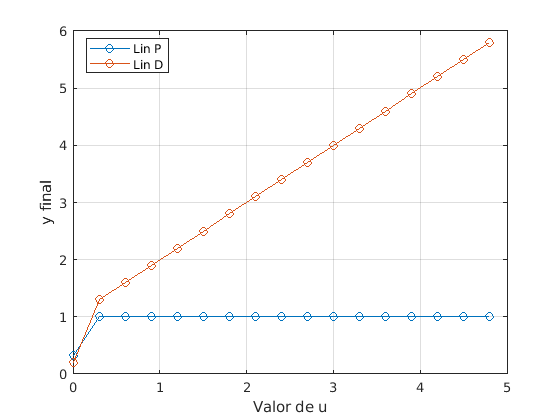

input = 0:0.3:5;
Size = length(input);
LP = zeros(1,Size);
LD = zeros(1,Size);

for i = 1:Size
    u = input(i);
    options = simset('SrcWorkspace','current');
    sim('PresaDepredador_ejm2',[],options);
    LP(i) = P(end);
    LD(i) = D(end);
end

figure
plot(input,LP, '-o',input,LD,'-o')
grid on
xlabel('Valor de u')
ylabel('y final')
legend('Lin P','Lin D','Location',"best")

**Entrada step**

1. Definición de la entrada para observar el comportamiento general del modelo

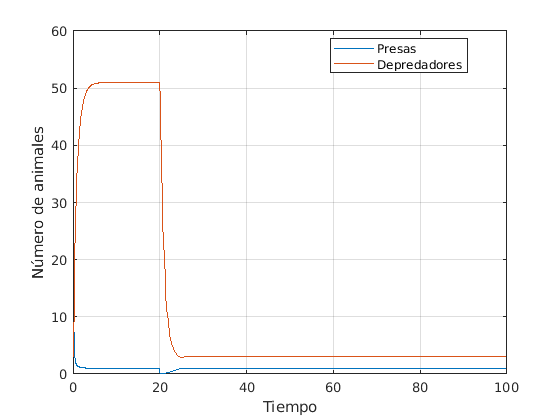

% Parámetros de la entrada
StepTime = 20;
u1 = 50;
u2 = 2;

options = simset('SrcWorkspace','current');
out = sim('PresaDepredador_step',[],options);

figure
plot(t,P)
hold on
grid on
plot(t,D)
xlabel('Tiempo')
ylabel('Número de animales')
legend('Presas', 'Depredadores','Location',"best")

Al igual que en el anterior caso, se varía los valores de la entrada *u2 *de 0 a 5 con pasos de 0.3, con entrada *u1 *igual a 50.  

Despues del tiempo 20 se activa la entrada.

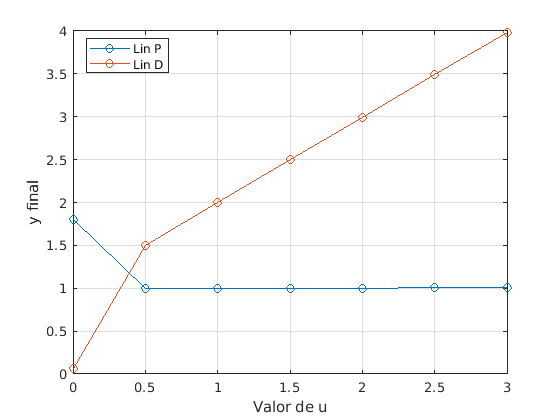


input = 0:0.5:3;
Size = length(input);
LP = zeros(1,Size);
LD = zeros(1,Size);

for i = 1:Size
    u2 = input(i);
    options = simset('SrcWorkspace','current');
    sim('PresaDepredador_step',[],options);
    LP(i) = P(end);
    LD(i) = D(end);
end

figure
plot(input,LP, '-o',input,LD,'-o')
grid on
xlabel('Valor de u')
ylabel('y final')
legend('Lin P','Lin D','Location',"best")